syms s C1 R1 
Av5 = R1/((1/C1*s)+R1)

$$Av5 = \frac{R_{1}}{R_{1}+\frac{s}{C_{1}}}$$

C1 = 0.0047; R1 = 10; 
Av5 =subs(Av5)

$$Av5 = \frac{10}{\frac{10000\,s}{47}+10}$$


[symNum, symDen] = numden(Av5)

$$symNum = 47$$

$$symDen = 1000\,s+47$$

num = sym2poly(symNum)

num = 47

den = sym2poly(symDen)

den =         1000          47


Av5TF = tf(num,den)

Av5TF =
 
      47
  -----------
  1000 s + 47
 
Continuous-time transfer function.
Model Properties


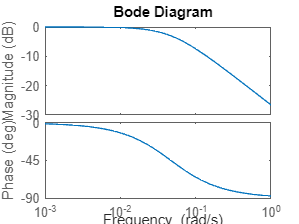

bode(Av5TF)


opts = bodeoptions

opts =

                   FreqUnits: 'rad/s'
                   FreqScale: 'log'
                    MagUnits: 'dB'
                    MagScale: 'linear'
                  MagVisible: 'on'
             MagLowerLimMode: 'auto'
                  PhaseUnits: 'deg'
                PhaseVisible: 'on'
               PhaseWrapping: 'off'
               PhaseMatching: 'off'
           PhaseMatchingFreq: 0
    ConfidenceRegionNumberSD: 1
                 MagLowerLim: -Inf
          PhaseMatchingValue: 0
         PhaseWrappingBranch: -180
                  IOGrouping: 'none'
                 InputLabels: [1×1 struct]
                OutputLabels: [1×1 struct]
                InputVisible: {'on'}
               OutputVisible: {'on'}
                       Title: [1×1 struct]
                      XLabel: [1×1 struct]
                      YLabel: [1×1 struct]
                   TickLabel: [1×1 struct]
                        Grid: 'off'
                   GridColor: [0.1500 0.1500 0.1500]
     

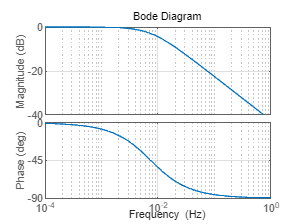

opts.Grid = 'on';
opts.FreqUnits = 'Hz';
bode(Av5TF, opts)

%only mag
opts = bodeoptions

opts =

                   FreqUnits: 'rad/s'
                   FreqScale: 'log'
                    MagUnits: 'dB'
                    MagScale: 'linear'
                  MagVisible: 'on'
             MagLowerLimMode: 'auto'
                  PhaseUnits: 'deg'
                PhaseVisible: 'on'
               PhaseWrapping: 'off'
               PhaseMatching: 'off'
           PhaseMatchingFreq: 0
    ConfidenceRegionNumberSD: 1
                 MagLowerLim: -Inf
          PhaseMatchingValue: 0
         PhaseWrappingBranch: -180
                  IOGrouping: 'none'
                 InputLabels: [1×1 struct]
                OutputLabels: [1×1 struct]
                InputVisible: {'on'}
               OutputVisible: {'on'}
                       Title: [1×1 struct]
                      XLabel: [1×1 struct]
                      YLabel: [1×1 struct]
                   TickLabel: [1×1 struct]
                        Grid: 'off'
                   GridColor: [0.1500 0.1500 0.1500]
     

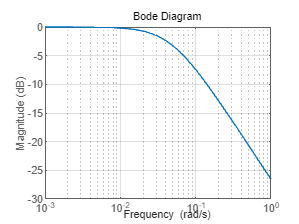

opts.Grid = 'on';
opts.PhaseVisible = 'off';
%opts.XLim = [10^-4 10^3];
%opts.YLim = {[-60 60], [-90 0]};
% opts.FreqUnits = 'Hz';
bode(Av5TF, opts)